% %1
% T = 100; dt = 0.01; %период и частота дискретизации
% t=-T/2:dt:T/2; % Вектор времени
% V = 1/dt; % Ширина диапазона частот
% dv = 1/T; % Шаг частоты
% v = -V/2 : dv : V/2; % Набор частот
% 
% y = 1.*(-1/2<=t & t<1/2)+0.*(t>=1/2 | t<-1/2);
% U = sinc(v);
% 
% f = figure;
% hold on
% p1 = plot(t, y);
% p1.LineWidth = 1.5;
% grid on
% xlabel("t")
% xlim([-2 2])
% ylim([-0.5 1.5])
% xticks(-2:1/2:2)
% legend('$\Pi (t)$','Interpreter','latex')
% hold off
% saveas(f,'C:\LATEX\Fourier_analiz\Fourier_5\1_1u.png');
% 
% f1 = figure;
% hold on
% p1 = plot(t, U);
% p1.LineWidth = 1.5;
% grid on
% xlabel("\nu")
% xlim([-2 2])
% ylim([-0.5 1.5])
% xticks(-2:1/2:2)
% legend('$\hat \Pi (\nu)$','Interpreter','latex')
% hold off
% saveas(f1,'C:\LATEX\Fourier_analiz\Fourier_5\1_1uu.png');


%2
% T = 100; dt = 0.5; %период и частота дискретизации
% t=-T/2:dt:T/2; % Вектор времени
% V = 1/dt; % Ширина диапазона частот
% dv = 1/T; % Шаг частоты
% v = -V/2 : dv : V/2; % Набор частот
% 
% y = 1.*(-1/2<=t & t<1/2)+0.*(t>=1/2 | t<-1/2);
% 
% U = zeros(1,length(t)); %Фурье образ
% for k = 1 : length(t)
%     U(k)=trapz(t,y.*exp(-1i*2*pi*v(k)*t)); % преобразование фурье
% end
% u = zeros(1,length(v));
% for k = 1 : length(v)
%     u(k)=trapz(v,U.*exp(1i*2*pi*v(k)*t)); % обратное преобразование Фурье
% end
% 
% f = figure;
% hold on
% p2 = plot(t, u);
% p2.LineWidth = 1.5;
% grid on
% xlabel("t")
% xlim([-2 2])
% ylim([-0.5 1.5])
% % xticks(-2:1/2:2)
% legend('$\Pi (t)$','Interpreter','latex')
% hold off
% % saveas(f,'C:\LATEX\Fourier_analiz\Fourier_5\1_222u.png');
% 
% f1 = figure;
% hold on
% p1 = plot(v, U);
% p1.LineWidth = 1.5;
% grid on
% xlabel("\nu")
% xlim([-2 2])
% ylim([-0.5 1.5])
% xticks(-2:1/2:2)
% legend('$\hat \Pi (\nu)$','Interpreter','latex')
% hold off
%saveas(f1,'C:\LATEX\Fourier_analiz\Fourier_5\1_222uu.png');

% %3
% T = 100; dt = 0.001; %период и частота дискретизации
% t=-T/2:dt:T/2; % Вектор времени
% V = 1/dt; % Ширина диапазона частот
% dv = dt; % Шаг частоты
% v = -V/2 : dv : V/2; % Набор частот
% 
% y = 1.*(-1/2<=t & t<1/2)+0.*(t>=1/2 | t<-1/2);
% 
% U = dt*fftshift(fft(y));
% u = (1/dt)*ifft(ifftshift(U));
% 
% f = figure;
% hold on
% p1 = plot(t, u);
% p1.LineWidth = 1.5;
% grid on
% xlabel("t")
% xlim([-2 2])
% ylim([-0.5 1.5])
% xticks(-2:1/2:2)
% legend('$\Pi (t)$','Interpreter','latex')
% hold off
% % saveas(f,'C:\LATEX\Fourier_analiz\Fourier_5\1_33u.png');
% 
% f1 = figure;
% hold on
% p1 = plot(t, U);
% p1.LineWidth = 1.5;
% grid on
% xlabel("\nu")
% xlim([-2 2])
% ylim([-1 1.5])
% xticks(-2:1/2:2)
% legend('$\hat \Pi (\nu)$','Interpreter','latex')
% hold off
% saveas(f1,'C:\LATEX\Fourier_analiz\Fourier_5\1_33uu.png');

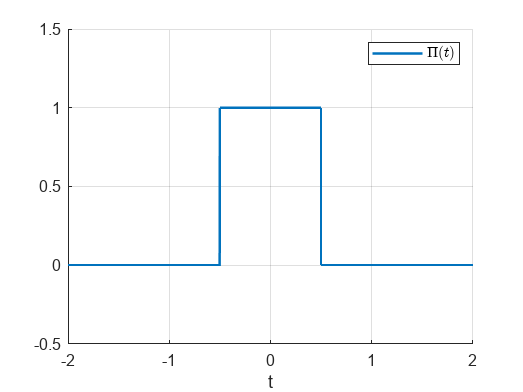

%4
% t0=-50;
% dt=0.001;
% t=t0:dt:-t0;
% dv =1/abs(t0);
% V = 1/dt;
% v = -V:dv:V;
% y = 1.*(-1/2<=t & t<1/2)+0.*(t>=1/2 | t<-1/2);
% 
% U=dt*fftshift(fft(ifftshift(y)));
% 
% % U= U* dt.*exp(-2*pi*1i*v*t0);
% % U = dt*fftshift(fft(y))*koef;
% 
% f = figure;
% hold on
% p1 = plot(t, u);
% p1.LineWidth = 1.5;
% grid on
% xlabel("t")
% xlim([-2 2])
% ylim([-0.5 1.5])
% % xticks(-2:1/2:2)
% legend('$\Pi (t)$','Interpreter','latex')
% hold off
% saveas(f,'C:\LATEX\Fourier_analiz\Fourier_5\1_4u.png');


% f1 = figure;
% hold on
% p1 = plot(t, U);
% p1.LineWidth = 1.5;
% grid on
% xlabel("\nu")
% xlim([-1 1])
% ylim([-1 1.5])
% xticks(-2:1/2:2)
% legend('$\hat \Pi (\nu)$','Interpreter','latex')
% hold off
% saveas(f1,'C:\LATEX\Fourier_analiz\Fourier_5\1_4uu.png');